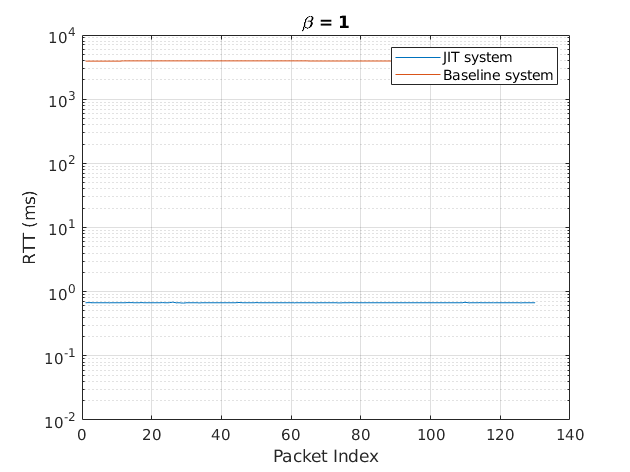


RTT_JIT_1  = [0.000472065,0.000476043,0.000471846,0.000471990,0.000472920,0.000471477,0.000471249,0.000470190,0.000471423,0.000472323,0.000473379,0.000471084,0.000476550,0.000474171,0.000472092,0.000471594,0.000474381,0.000470955,0.000473211,0.000471780,0.000470802,0.000471528,0.000474324,0.000471396,0.000470979,0.000487347,0.000470175,0.000470883,0.000462294,0.000472452,0.000470874,0.000471153,0.000470442,0.000469866,0.000472395,0.000471903,0.000471684,0.000471423,0.000472116,0.000471120,0.000471522,0.000470526,0.000471081,0.000472338,0.000478107,0.000472749,0.000470661,0.000471147,0.000471363,0.000475512,0.000470484,0.000471288,0.000471228,0.000472746,0.000471858,0.000470544,0.000472662,0.000471318,0.000471321,0.000471288,0.000470079,0.000471384,0.000472584,0.000471150,0.000471243,0.000471609,0.000470001,0.000470862,0.000472257,0.000472551,0.000472377,0.000471459,0.000470463,0.000469569,0.000471282,0.000472407,0.000473490,0.000473049,0.000471699,0.000470793,0.000471060,0.000470514,0.000471798,0.000470989,0.000471573,0.000472365,0.000471246,0.000471081,0.000471438,0.000470910,0.000470943,0.000472860,0.000471954,0.000471336,0.000471657,0.000471033,0.000470718,0.000472947,0.000472116,0.000471507,0.000472698,0.000470871,0.000470820,0.000472203,0.000472626,0.000472917,0.000471441,0.000471219,0.000470976,0.000482721,0.000469887,0.000471738,0.000472215,0.000473880,0.000471339,0.000471426,0.000471537,0.000470871,0.000471852,0.000472947,0.000472224,0.000471801,0.000472470,0.000471297,0.000471150,0.000469767,0.000471579,0.000470901,0.000470556,0.000470658];
RTT_JIT_1 = RTT_JIT_1*1000+0.2;

RTT_BL_1 = Process_delay_client + 0.144 + 98*200*0.2;

packet = (1:length(RTT_JIT_1));

semilogy(packet, RTT_JIT_1); 
hold on;
semilogy(packet, RTT_BL_1(1:length(RTT_JIT_1)));

grid on;
xlabel("Packet Index")
ylabel("RTT (ms)")
ylim([10e-3 10000])
legend("JIT system","Baseline system")
title('\beta = 1')